# 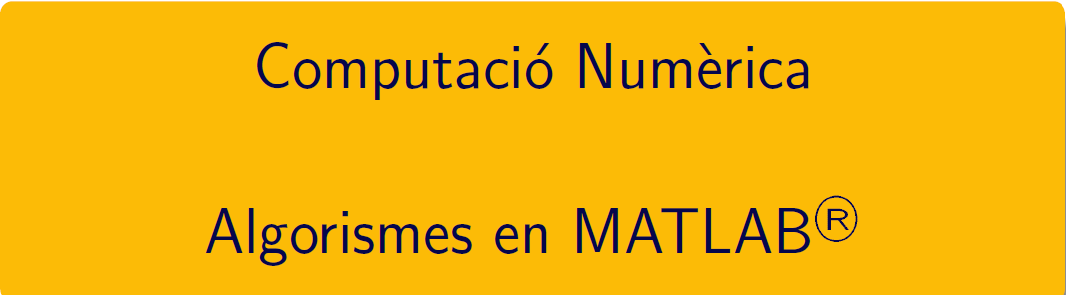

# Pràctica 1 - Conceptes Bàsics

## 1. Introducció a MATLAB

[ Cleve’s Corner: Cleve Moler on Mathematics and Computing](https://blogs.mathworks.com/cleve/)

[A Brief History of MATLAB](https://es.mathworks.com/company/newsletters/articles/a-brief-history-of-matlab.html?s_tid=srchtitle)

## 2. Exemple mètode iteratiu: convergència 

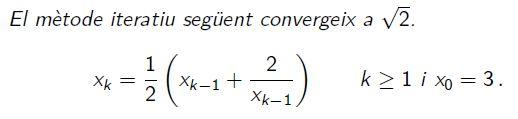

Calculeu els sis primers iterats, no conservem els valors càlculats

xk = 3;
for k = 1:6
    xk = (xk + 2/xk)/2
end

xk = 1.8333

xk = 1.4621

xk = 1.4150

xk = 1.4142

xk = 1.4142

xk = 1.4142

Calculeu els sis primers iterats, conservem els valors càlculats

format shortG
x = 3; 
e = abs(x - sqrt(2));
R = [0,x,e];
for k = 1:6
    x = 1/2*(x + 2/x);
    e = abs(x - sqrt(2));
    R = [R; k,x,e];
end
T = array2table(R,'VariableNames',{'k','x_k','error_absolut'}); disp(T)

    k     x_k      error_absolut
    _    ______    _____________

    0         3         1.5858  
    1    1.8333        0.41912  
    2    1.4621       0.047908  
    3     1.415     0.00078487  
    4    1.4142     2.1767e-07  
    5    1.4142     1.6653e-14  
    6    1.4142     2.2204e-16  



Calculeu els sis primers iterats, totes les iteracions en un vector, resultat en una estructura table.

% format shortG
x(1) = 3;
for k = 2:7
    x(k) = (x(k-1) + 2/x(k-1))/2;
end
ea = abs(x - sqrt(2));
er = ea/sqrt(2);
R = [x; ea; er]';
T = array2table(R,...
    'VariableNames',{'x_k','ea_k','er_k'})

T = 7×3 table
     x_k         ea_k          er_k   
    ______    __________    __________

         3        1.5858        1.1213
    1.8333       0.41912       0.29636
    1.4621      0.047908      0.033876
     1.415    0.00078487    0.00055499
    1.4142    2.1767e-07    1.5392e-07
    1.4142    1.6653e-14    1.1776e-14
    1.4142    2.2204e-16    1.5701e-16


Calculeu els ¿¿¿tots ???  els iterats, com s'atura el bucle

% Totes les iteracions en un vector
y(1) = 3;
k = 2;
while k < 70
    y(k) = (y(k-1)+2/y(k-1))/2;
    k = k+1;
end
ea = abs(y-sqrt(2));
er = ea / sqrt(2);
R = [(1:k-1); y; ea; er]'
T = array2table(R,...
    'VariableNames',{ 'k','x_k','ea_k','er_k'})

## 3. Aritmètica de PUNT FLOTANT

[Floating Point Arithmetic Before IEEE 754](https://blogs.mathworks.com/cleve/2019/01/18/floating-point-arithmetic-before-ieee-754/)

[A Glimpse into Floating-Point Accuracy](https://blogs.mathworks.com/loren/2006/08/23/a-glimpse-into-floating-point-accuracy/?s_tid=srchtitle)  o  [Floating Point Numbers](https://es.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html)

Exercici 1.- Nombres binaris i nombres decimals

- Convertim el nombre 23.125 a binari:

[S,E,F] = ieee754(23.125)

S = '0'

E = '10000000011'

F = '0111001000000000000000000000000000000000000000000000'

- part entera, restes de dividir per 2

y = fix(x); r = rem(y,2); T = [y,r];
y = fix(y/2); r = rem(y,2); T = [T; y,r];

% b = num2str(T(:,2));
% fprintf('El nombre %f en binari és %s\n',fix(x),b)

- part fraccionaria, multipliquem per 2 i ens quedem amb la part entera

z = x-fix(x);
y = 2*z; r = fix(y);  T = [z,r]; z = y-r;
y = 2*z; r = fix(y);  T = [T; z,r]; z = y-r;

% b2 = num2str(T(:,2));
% fprintf('El nombre %f en binari és %s\n',x-fix(x),b2)
% fprintf('El nombre %f en binari és %s.%s\n',x,b,b2)

### LECTURA OBLIGATÒRIA: [Floating Points: IEEE Standard Unifies Arithmetic Model](https://es.mathworks.com/company/newsletters/articles/floating-points-ieee-standard-unifies-arithmetic-model.html?s_tid=answers_rc2-3_p6_Topic)

Toby Driscoll (2021). IEEE 754 binary representation ([https://www.mathworks.com/matlabcentral/fileexchange/25326-ieee-754-binary-representation),](https://www.mathworks.com/matlabcentral/fileexchange/25326-ieee-754-binary-representation),) MATLAB Central File Exchange. Retrieved February 15, 2021

[S,E,F] = ieee754(2^52)

S = '0'

E = '10000110011'

F = '0000000000000000000000000000000000000000000000000000'

**Avoiding Common Problems with Floating-Point Arithmetic**

Example 1 — Round-Off or What You Get Is Not What You Expect

- 4/3 no té fracció binària exacte

a = 4/3, b = a - 1, c= b+b+b, e=1-c

a =        1.3333


b =       0.33333


c =             1


e =    2.2204e-16


[S,E,F] = ieee754(a)

S = '0'

E = '01111111111'

F = '0101010101010101010101010101010101010101010101010101'

- 0.1 no té representació binària exacte

a = 0.0;
for i = 1:10
  a = a + 0.1;
end
a == 1

ans = logical
   0


[~,~,F] = ieee754(0.1)

F = '1001100110011001100110011001100110011001100110011010'

- L'ordre de les operacions pot fer variar el resultat del càlcul

b = 1e-16 + 1 - 1e-16;
c = 1e-16 - 1e-16 + 1;
b == c

ans = logical
   0


- Hi ha "gaps" entre els números de punt flotant.  

(2^53 + 1) - 2^53

ans =      0


- La representació de $\pi$ comporta que 

sin(pi), sin(pi) == 0

ans =    1.2246e-16


ans = logical
   0


**Example 2 — Catastrophic Cancellation**

sqrt(1e-16 + 1) - 1

ans =      0


**Example 3 — Floating-Point Operations and Linear Algebra**

L'arrodoniment, la cancel·lació i altres caracterítiques de l'aritmètica de coma flotant es combinen per produir càlculs sorprenents en resoldre els problemes de l'àlgebra lineal. MATLAB adverteix que la següent matriu A està mal condicionada i, per tant, el sistema Ax = b pot ser sensible a petites pertorbacions:

A = diag([2 eps]);
b = [2; eps]; 
y = A\b

y =      1
     1


**Example 4 — "Soroll numèric"**

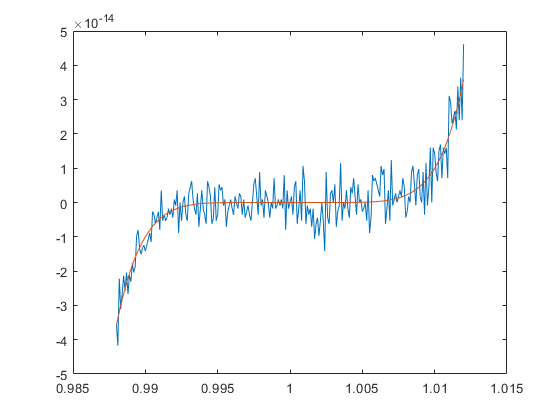

x = 0.988:.0001:1.012;
y = x.^ 7- 7* x.^ 6+ 21* x.^ 5- 35* x.^ 4+ 35* x.^ 3 - 21* x.^ 2+ 7* x- 1;
z = (x-1).^7;
plot( x, y, x, z)

## 5. Algorismes: Estabilitat numèrica i problemes ben condicionats

### Funcions

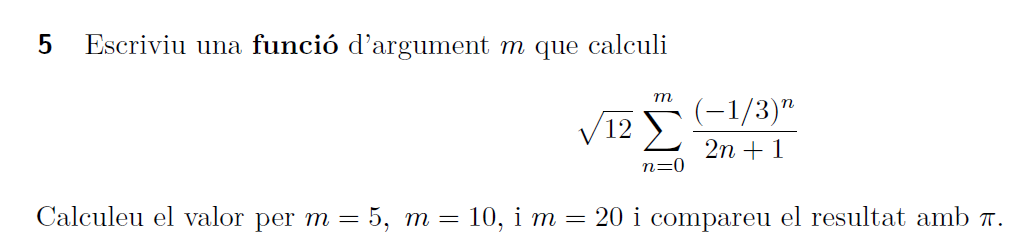

format longG
S5 = sumapi(5); S10 = sumapi(10); S20 = sumapi(20);
R = [S5,S10,S20]; r = abs(R-pi); R = [R;r]';
T = array2table(R,...
    'VariableNames',{'S','|S-pi|'},"RowNames",{'m=5','m=10','m=20'}); disp(T)

                   S                   |S-pi|       
            ________________    ____________________

    m=5     3.14130878546288    0.000283868126909947
    m=10    3.14159330450308     6.5091328815825e-07
    m=20    3.14159265359564    5.84199355557757e-12



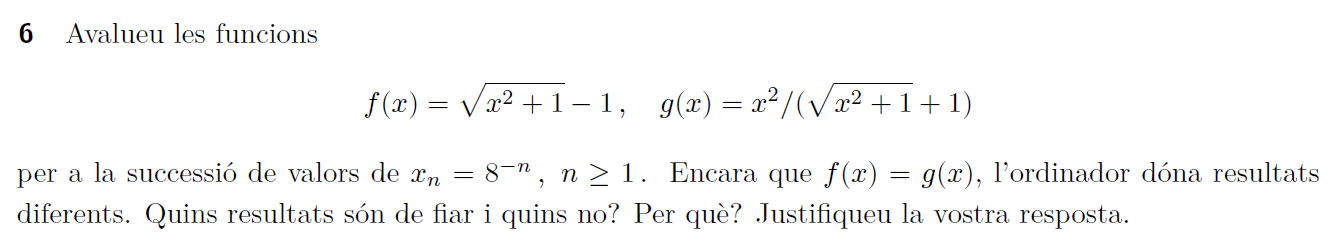

format shortG
f = @(x) sqrt(x.^2 + 1) - 1;
g = @(x) x.^2./(sqrt(x.^2 + 1) + 1);
n = 1:15;
x = 8.^(-n);
R = [n; x; f(x); g(x)]';
T = array2table(R,...
    "VariableNames",{'n','8^(-n)','f(8^-n)','g(8^-n)'}); disp(T)

    n       8^(-n)       f(8^-n)       g(8^-n)  
    __    __________    __________    __________

     1         0.125     0.0077822     0.0077822
     2      0.015625    0.00012206    0.00012206
     3     0.0019531    1.9073e-06    1.9073e-06
     4    0.00024414    2.9802e-08    2.9802e-08
     5    3.0518e-05    4.6566e-10    4.6566e-10
     6    3.8147e-06     7.276e-12     7.276e-12
     7    4.7684e-07    1.1369e-13    1.1369e-13
     8    5.9605e-08    1.7764e-15    1.7764e-15
     9    7.4506e-09             0    2.7756e-17
    10    9.3132e-10             0    4.3368e-19
    11    1.1642e-10             0    6.7763e-21
    12    1.4552e-11             0    1.0588e-22
    13     1.819e-12             0    1.6544e-24
    14    2.2737e-13             0    2.5849e-26
    15    2.8422e-14             0     4.039e-28



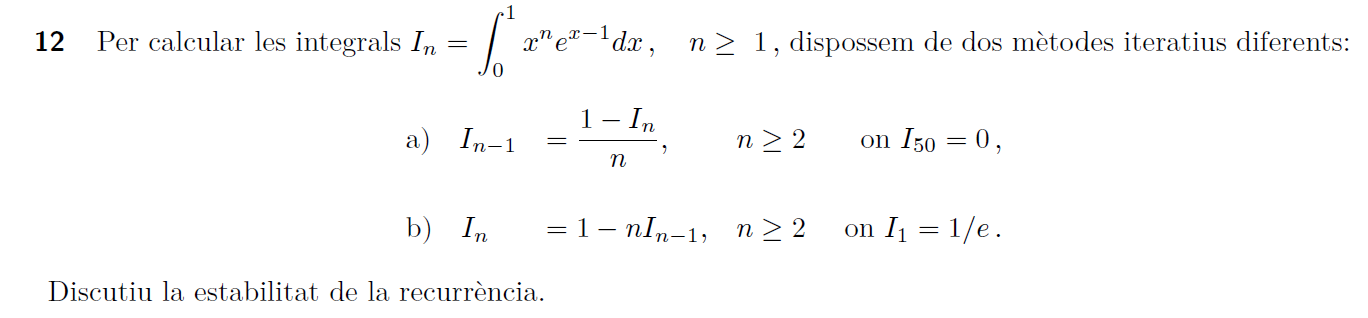

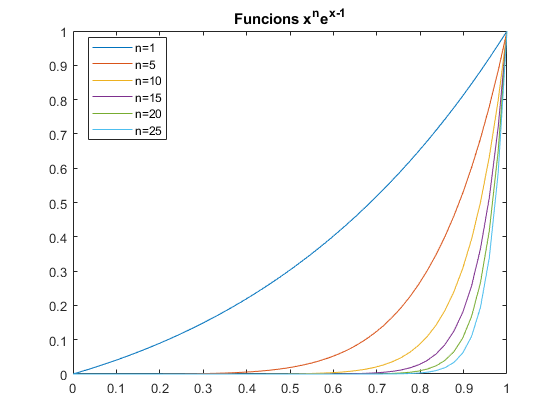

% a) correcte b) incorrecte
g= @(x,n) x.^n.*exp(x-1);
x = linspace(0,1,50);
plot(x, g(x,1)), hold on
for n = 1:5
    plot(x, g(x,n*5))
end
hold off
title('Funcions x^ne^{x-1}'),legend('n=1','n=5','n=10','n=15','n=20','n=25','Location','best')

- apartat a)

J(50) = 0;
for n = 50:-1:2
    J(n-1) = (1-J(n))/n;
end

- apartat b)

I(1) = exp(-1);
for n = 2:50
    I(n) = 1-n*I(n-1);
end

- valor aproximat per integració numèrica

for n = 1:50
    ve(n) = integral(@(x)x.^n.*exp(x-1),0,1);
end

- taula comparativa de resultats

n = 1:50;
R = [n; ve; J; I]';
T = array2table(R,...
    'VariableNames',{'n','ve','apartat a)','apartat b)'}); disp(T)

    n        ve       apartat a)    apartat b) 
    __    ________    __________    ___________

     1     0.36788      0.36788         0.36788
     2     0.26424      0.26424         0.26424
     3     0.20728      0.20728         0.20728
     4     0.17089      0.17089         0.17089
     5     0.14553      0.14553         0.14553
     6      0.1268       0.1268          0.1268
     7     0.11238      0.11238         0.11238
     8     0.10093      0.10093         0.10093
     9    0.091612     0.091612        0.091612
    10    0.083877     0.083877        0.083877
    11    0.077352     0.077352        0.077352
    12    0.071773     0.071773        0.071773
    13    0.066948     0.066948        0.066948
    14    0.062732     0.062732        0.062731
    15    0.059018     0.059018        0.059034
    16    0.055719     0.055719        0.055459

- taula comparativa d'errors

Re = [n;abs(ve-J); abs(ve-I)]';
Te = array2table(Re,...
    'VariableNames',{'n','apartat a)','apartat b)'}); disp(Te)

    n     apartat a)    apartat b)
    __    __________    __________

     1    5.5511e-17    5.5511e-17
     2    5.5511e-17    5.5511e-17
     3    5.5511e-17    1.1102e-16
     4             0    2.7756e-16
     5    2.7756e-17    1.4988e-15
     6             0    8.9373e-15
     7    1.3878e-17    6.2658e-14
     8             0    5.0113e-13
     9    1.3878e-17    4.5102e-12
    10    1.3878e-17    4.5101e-11
    11    1.3878e-17    4.9612e-10
    12    1.3878e-17    5.9534e-09
    13    1.3878e-17    7.7394e-08
    14             0    1.0835e-06
    15    6.9389e-18    1.6253e-05
    16    6.9389e-18    0.00026004
    17    1.3878e-17     0.0044208
    18    6.9389e-18      0.079574
    19    6.9389e-18        1.5119
    20    1.3878e-17        30.238
    21             0           635
    22    6.9389e-18         13970
    23    6.9389e-18    3.2131e+05
    24             0  

## Pràctica

## 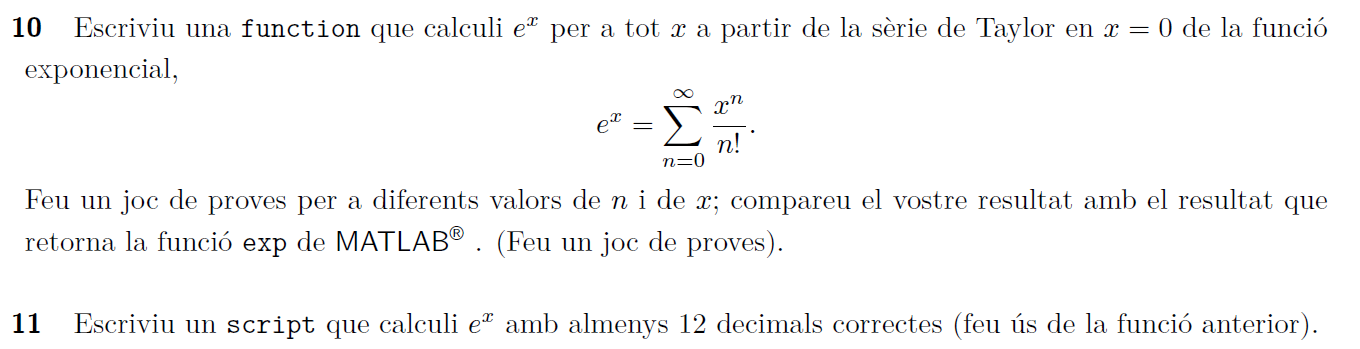 

format longG
x = 14.1; n = 40;
my_exp(x,n); my_exp(-x,n);

El valor de e^(14.1) calculat de Matlab és 1329083.28081209282391
El valor de e^(14.1) aproximat és 1329083.27494041924365; es tenen 1 decimals correctes i 8 xifres significatives

El valor de e^(-14.1) calculat de Matlab és 0.00000075239830
El valor de e^(-14.1) aproximat és 0.00000075239851; es tenen 12 decimals correctes i 6 xifres significatives



x = 3.52; n = 50;
my_exp(x,n); my_exp(-x,n);

El valor de e^(3.52) calculat de Matlab és 33.78442846384955
El valor de e^(3.52) aproximat és 33.78442846384909; es tenen 12 decimals correctes i 13 xifres significatives

El valor de e^(-3.52) calculat de Matlab és 0.02959943516789
El valor de e^(-3.52) aproximat és 0.02959943516804; es tenen 12 decimals correctes i 11 xifres significatives



x = 1.87; n = 20;
my_exp(x,n); my_exp(-x,n);

El valor de e^(1.87) calculat de Matlab és 6.48829639928671
El valor de e^(1.87) aproximat és 6.48829639928659; es tenen 12 decimals correctes i 13 xifres significatives

El valor de e^(-1.87) calculat de Matlab és 0.15412366181513
El valor de e^(-1.87) aproximat és 0.15412366181545; es tenen 12 decimals correctes i 11 xifres significatives



x = 17.22; n = 100;
my_exp(x,n); my_exp(-x,n);

El valor de e^(17.22) calculat de Matlab és 30098924.55466772615910
El valor de e^(17.22) aproximat és 30098924.55466771870852; es tenen 7 decimals correctes i 15 xifres significatives

El valor de e^(-17.22) calculat de Matlab és 0.00000003322378
El valor de e^(-17.22) aproximat és 0.00000003322413; es tenen 12 decimals correctes i 4 xifres significatives



`Document preparat per M. Àngela Grau Gotés, 8 d'octubre de 2020`